ts=0.6;
fs=1/ts

fs = 1.6667


N=512;
k=0:N-1;
td=k*ts;
p0=70;
f0=fs/6;%cumpliendo el teorema de nyquist
w=2*pi*f0

w = 1.7453

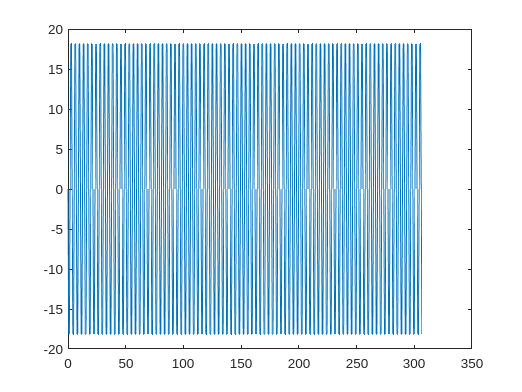

v0=12;
x_n=-(v0*w)*sin(w*td);
plot(td,x_n)

p=[x_n ;zeros(1,N)]'

p =          0         0
  -18.1380         0
  -18.1380         0
   -0.0000         0
   18.1380         0
   18.1380         0
    0.0000         0
  -18.1380         0
  -18.1380         0
   -0.0000         0


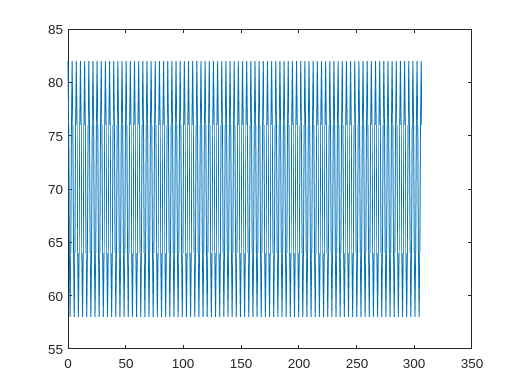

A=v0;
p_n=p0+A*cos(w*td);
figure
plot(td,p_n)

b=30%cm distancia entre robots o markers de la base del triangulo isosceles

b = 30

a=sqrt(p_n.^2+ (b/2)^2);%lados iguales del triangulo isosceles
h=p_n;
alpha123=asin(h./a);
alpha312=asin(b/2./a);
alpha231=pi-alpha123-alpha312;


for i=2:N
    Dalpha123=(alpha123(i)-alpha123(i-1))/ts;
    Dalpha312=(alpha312(i)-alpha312(i-1))/ts;
    Dalpha231=(alpha231(i)-alpha231(i-1))/ts;
    m2_21=M2_21(alpha123(i),alpha312(i),alpha231(i),Dalpha231,Dalpha123,Dalpha312);
    m2_12=M2_12(alpha123(i),alpha312(i),Dalpha123,Dalpha312);
    m2_123=M2_123(alpha123(i),alpha231(i),Dalpha123,Dalpha231,m2_12,m2_21);
    M2_123_inv=inv(m2_123);
    pn=M2_123_inv*[sin(alpha123(i)).*rot(alpha312(i))'.*p(i,[1 2])' - sin(alpha231(i)).*p(i,[1 2])';sin(alpha231(i)).*rot(alpha231(i))'.*p(i,[1 2])']

end

Error using vertcat
Dimensions of arrays being concatenated are not consistent.